We return to finding a root of the equation $xe^x=2$.

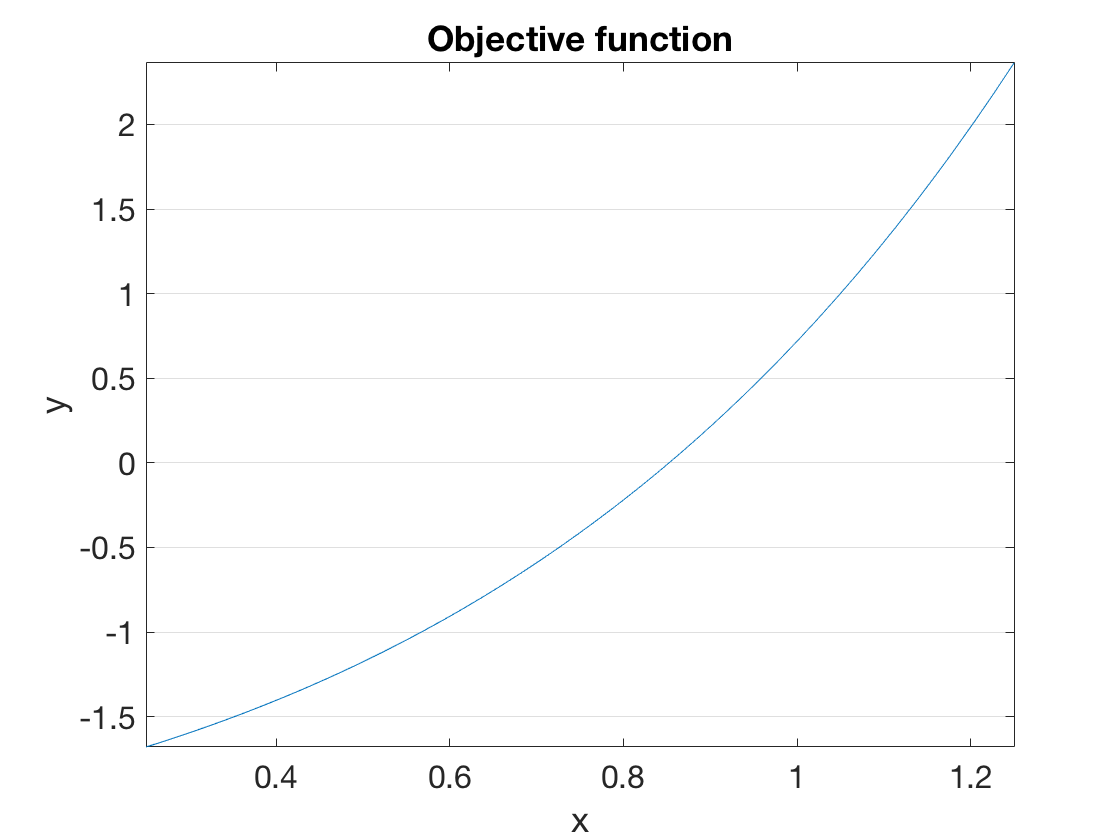

f = @(x) x.*exp(x) - 2;
fplot(f,[0.25 1.25])
set(gca,'ygrid','on')  % ignore this line
xlabel('x'), ylabel('y')    % ignore this line
title('Objective function')    % ignore this line

From the graph, it's clear that there is a root near $x=1$. To be more precise, there is a root in the interval $[0.5,1]$. So let us take the endpoints of that interval as *two* initial approximations. 

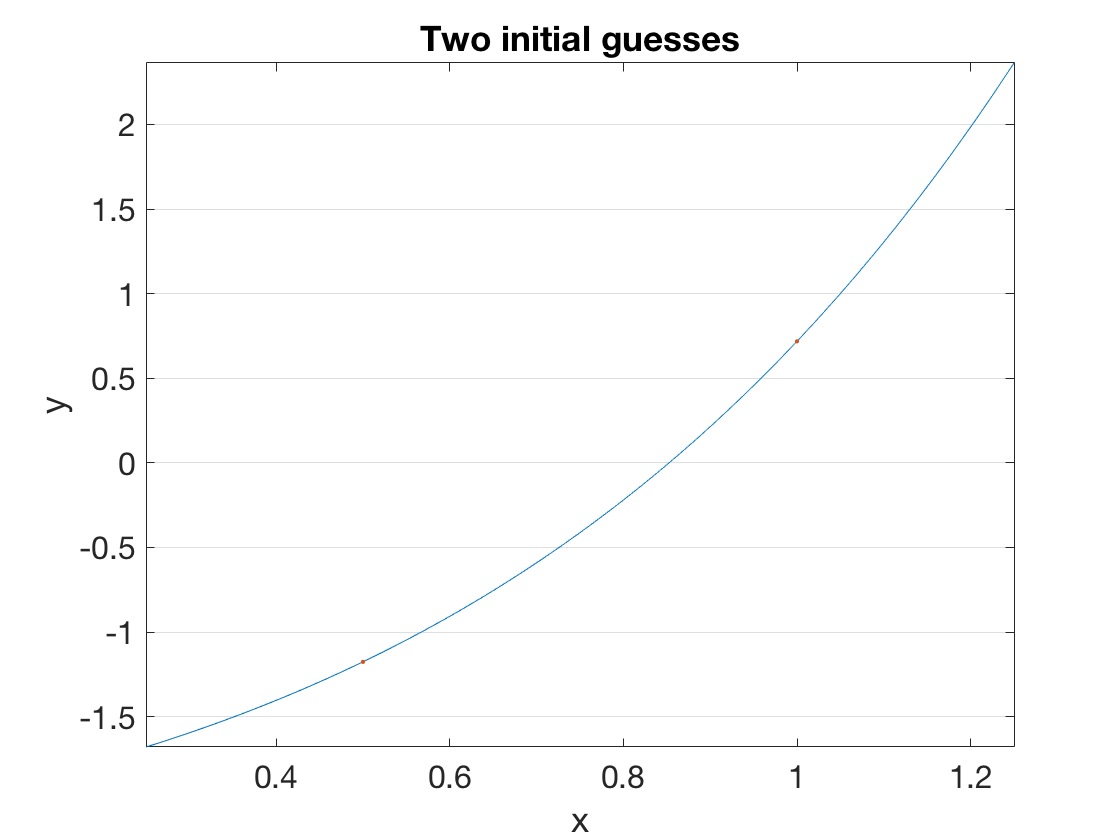

x1 = 1;    f1 = f(x1);
x2 = 0.5;  f2 = f(x2);
hold on, plot([x1 x2],[f1 f2],'.')
title('Two initial guesses')    % ignore this line

Instead of constructing the tangent line by evaluating the derivative, we can construct a linear model function by drawing the line between the two points $\bigl(x_1,f(x_1)\bigr)$ and $\bigl(x_2,f(x_2)\bigr)$. This is called a *secant line*.

slope2 = (f2-f1) / (x2-x1);
secant2 = @(x) f2 + slope2*(x-x2);

As before, the next value in the iteration is the root of this linear model. 

fplot(secant2,[0.25 1.25],'k--')
x3 = x2 - f2/slope2;
f3 = f(x3)

f3 =   -1.7768e-01


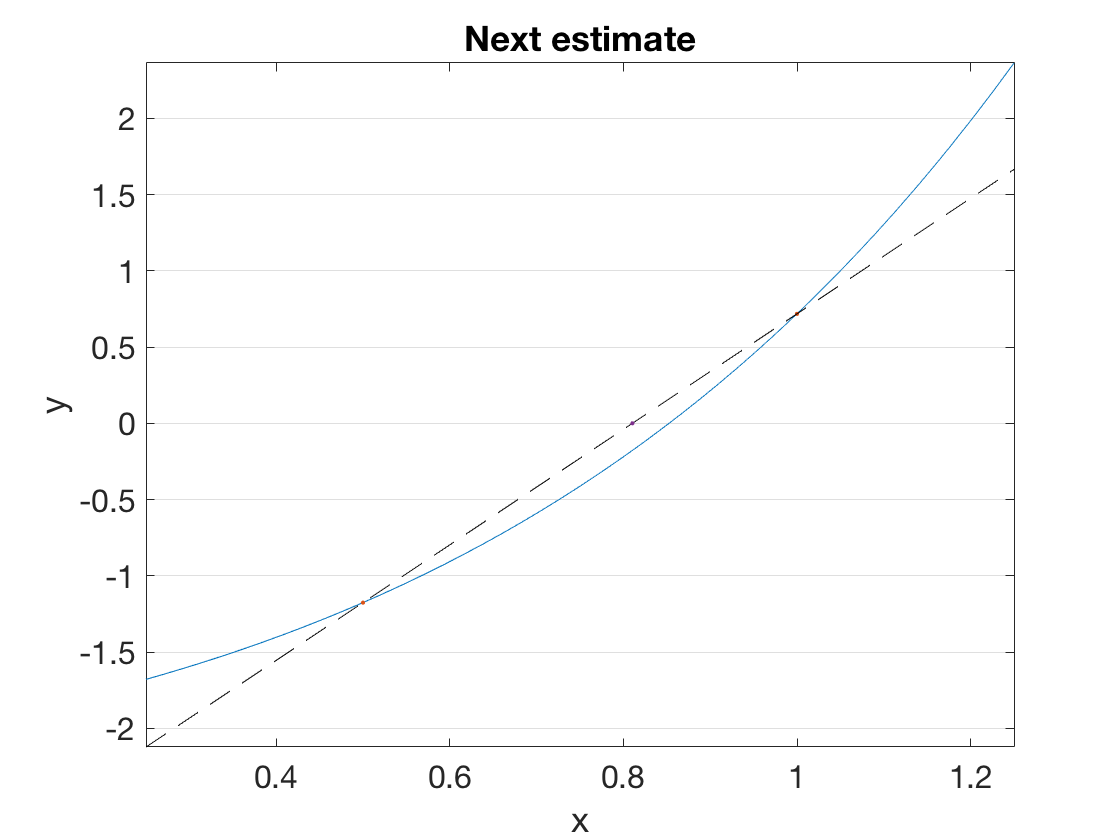

plot(x3,0,'.')
title('Next estimate')    % ignore this line

For the next linear model, we use the line through the two most recent points. The next iterate is the root of that secant line, and so on.

slope2 = (f3-f2) / (x3-x2);
x4 = x3 - f3/slope2;
f4 = f(x4)

f4 =    5.7181e-02
